# Eksamensæt F21

**M3NUM1 Anvendte Numeriske Metoder -- 16-01-2023**

**Mathias Bruun Houmøller -- 202006837 -- Au666097**

## Opgave 1

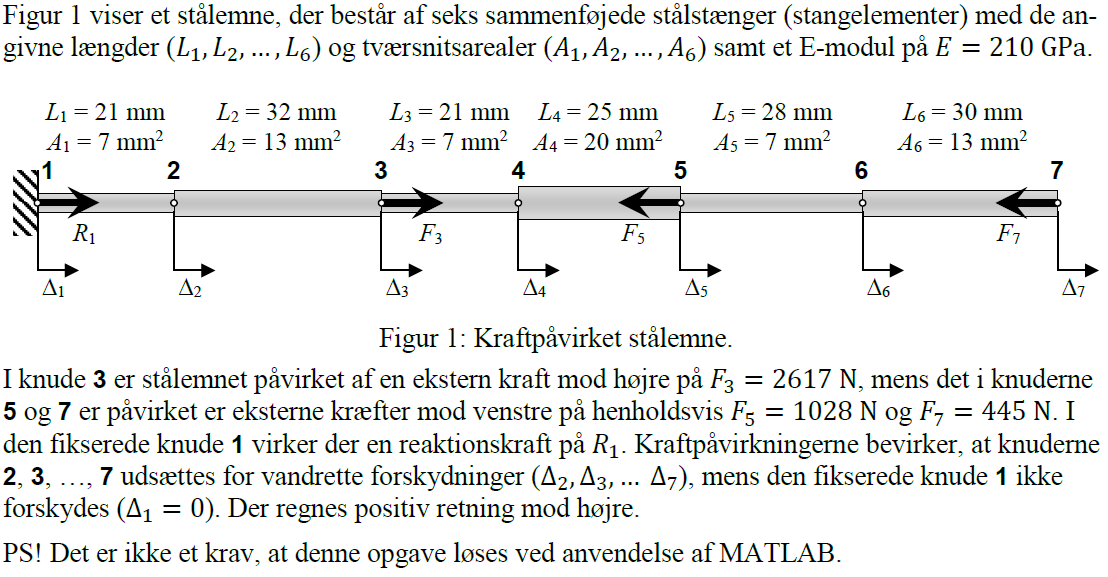

clear
format short %formater resultater til 4 decimaler
u = symunit; %Laver symbolske si enheder
% separateUnits(x)
% unitConvert(expr,units)

### (1a)

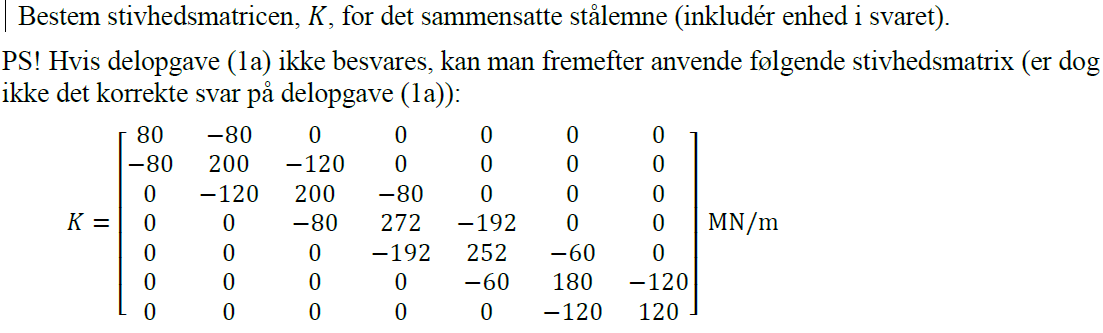

E = 210*1e9; %Pa
L = [21 32 21 25 28 30] / 1e3;
A = [7  13 7 20 7 13]/ 1e6;
n = 6; %antal sektioner
K = zeros(n+1,n+1); 

for j = 1:n 
    k = A(j)*E/L(j); % Fjederkonstant (N/m) for stangelement j 
    Kelem = [k -k; -k k]; % Stivhedsmatrix (N/m) for stangelement j
    K(j:j+1,j:j+1) = K(j:j+1,j:j+1) + Kelem; % Opdatér K 
end 
K_MN_pr_m = K/1e6 % K omregnet til/vist i MN/m

K_MN_pr_m =    70.0000  -70.0000         0         0         0         0         0
  -70.0000  155.3125  -85.3125         0         0         0         0
         0  -85.3125  155.3125  -70.0000         0         0         0
         0         0  -70.0000  238.0000 -168.0000         0         0
         0         0         0 -168.0000  220.5000  -52.5000         0
         0         0         0         0  -52.5000  143.5000  -91.0000
         0         0         0         0         0  -91.0000   91.0000


Vi får nu K matrixen i MN/m.

### (1b)

F = [0 2617 0 -1028 0 -445]';

Kred = K(2:7,2:7);
D = Kred\F;
D_my = D'*1e6;

tab = table(D_my', VariableNames={'Forskydning i elementerne(\mu m)'}, ...
    RowNames={'\Delta_2', '\Delta_3', '\Delta_4', '\Delta_5', '\Delta_6', '\Delta_7'})

tab = 6×1 table
                Forskydning i elementerne(\mu m)
                ________________________________

    \Delta_2                  16.343            
    \Delta_3                  29.752            
    \Delta_4                  8.7095            
    \Delta_5               -0.058333            
    \Delta_6                 -8.5345            
    \Delta_7                 -13.425            


%angevet i micro meter

## Opgave 2

clear

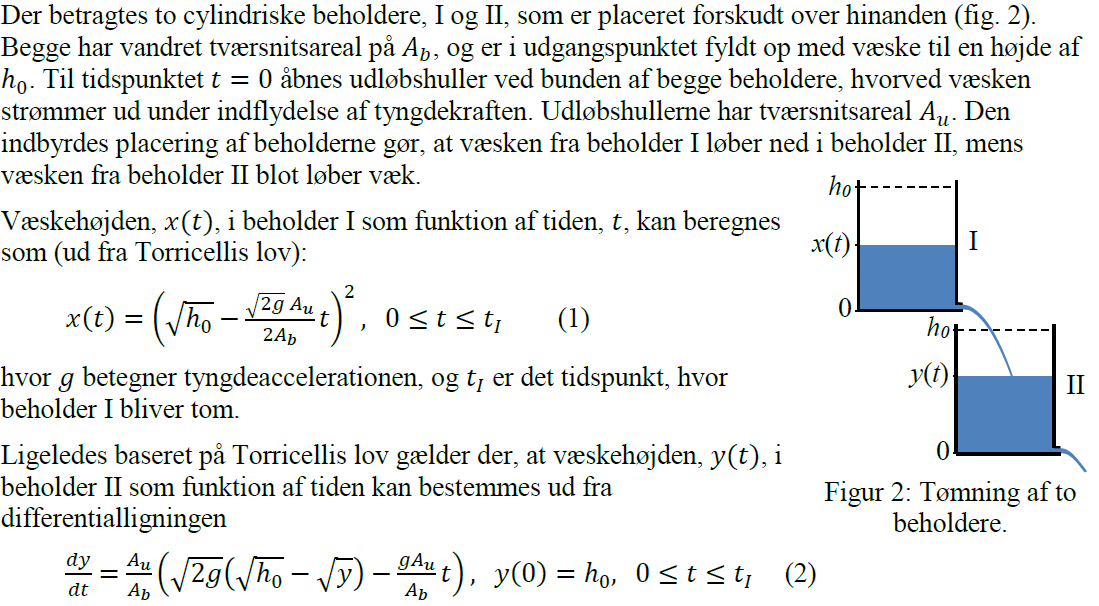

### (2a)

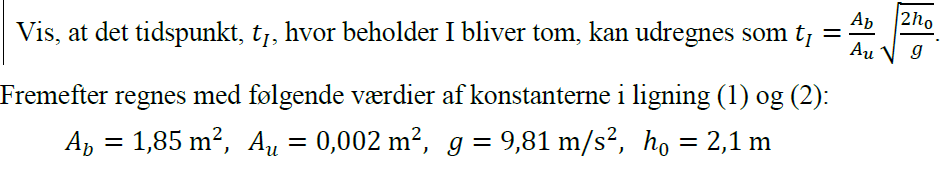


$$0 = \left( \sqrt{h_0} - \frac{\sqrt{2g} A_u}{2A_b} \cdot t_I \right)^2 \\
0 = \left( \sqrt{h_0} - \frac{\sqrt{2g} A_u}{2A_b} \cdot \frac{A_b \sqrt{2h_0}}{A_u \sqrt{g}} \right)^2 $$


Vi ser at $\sqrt{2} \cdot \sqrt{2} = 2$ og at det højre led går ud og bliver til $ \sqrt{h_0}$


$$0 = \left( \sqrt{h_0} - \sqrt{h_0} \right)^2 = 0$$


Vi har dermed at beholder I er tom ved tiden $t_I$.

### (2b)

Løs differentialligningen i ligning (2) ved brug af Eulers metode fra 𝑡_I=0 til det nærmeste man kan komme på tidspunktet 𝑡𝑡𝐼𝐼, når der anvendes tidsskridt på 60 s. I besvarelsen skal både talresul-tater og beregningsformler anføres for hver iteration (på tabelform vha. fx Excel). Hvad bliver ifølge løsningen væskehøjden i beholder II efter 480 s?

A_b = 1.85; %m^2
A_u = 0.002; %m^2
g = 9.81; %m/s^2
h_0 = 2.1; %m
t_start = 0;
t_I = A_b / A_u * sqrt(2 * h_0 / g);

dYdt = @(t,Y) A_u / A_b * (sqrt(2 * g) * (sqrt(h_0) - sqrt(Y(1))) - g * A_u / A_b * t); 
Y0 = h_0; 
tidsinterval = [t_start t_I]; 
h = 60; 
[t,Y] = eulode(dYdt,tidsinterval,Y0,h); 

disp(table(t,Y,'VariableNames',{'t, (s)','x, (m)'}))

    t, (s)    x, (m) 
    ______    _______

         0        2.1
        60        2.1
       120     2.0587
       180     1.9803
       240     1.8685
       300      1.727
       360     1.5594
       420     1.3693
       480     1.1606
       540     0.9372
       600    0.70394
    605.25    0.68318



%der plottes
plot(t,Y, 'DisplayName', 'Eulers metode') %data plottes
hold on
xline(480, '--', 'DisplayName', 't=480')

% formalier
title('Vand i beholder II', 'interpreter', 'latex')
xlabel('Tid $t$ (s)', 'interpreter', 'latex')
ylabel('Vandhojde $x$ (m)', 'interpreter', 'latex')
grid('minor')


**Efter 480 sekunder ses det at vi har en vandstand i beholder II på 1,16 m.**

### (2c)

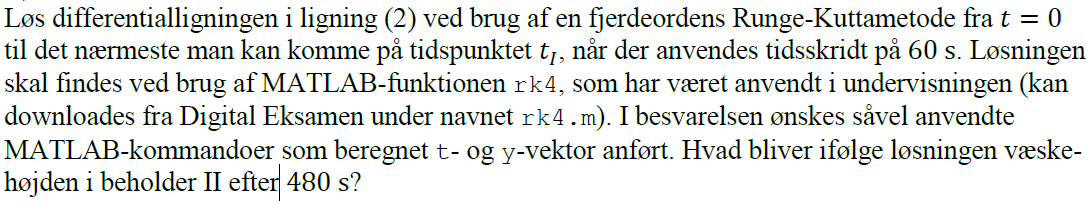

dYdt = @(t,Y) A_u / A_b * (sqrt(2 * g) * (sqrt(h_0) - sqrt(Y(1))) - g * A_u / A_b * t); 

[t,Y] = rk4(dYdt,tidsinterval,Y0,h);
disp(table(t,Y,'VariableNames',{'t, (s)','x, (m)'}))

    t, (s)    x, (m) 
    ______    _______

       0          2.1
      60         2.08
     120       2.0227
     180       1.9316
     240       1.8103
     300       1.6621
     360       1.4906
     420       1.2992
     480       1.0918
     540      0.87259
     600       0.6466



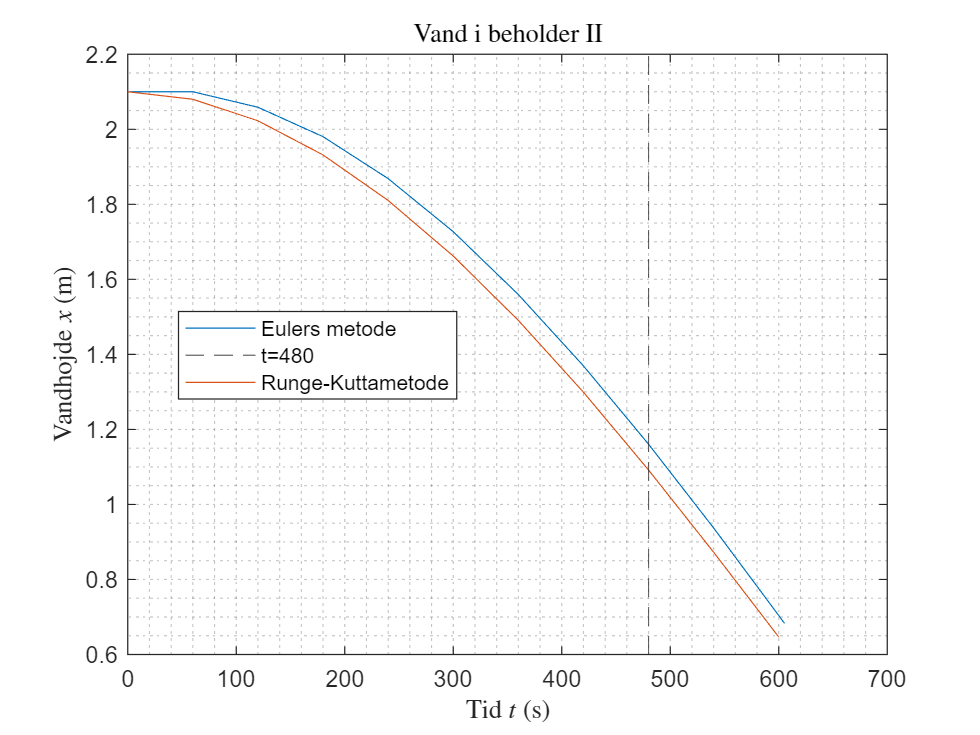

%der plottes
plot(t,Y, 'DisplayName', 'Runge-Kuttametode') %data plottes
legend('location', 'best')
hold off

**Vandhøjden i beholder II er således 1,09 m efter 480 sekunder**

### (2d)

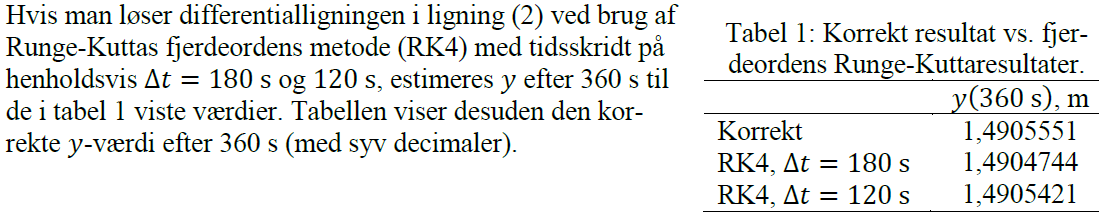

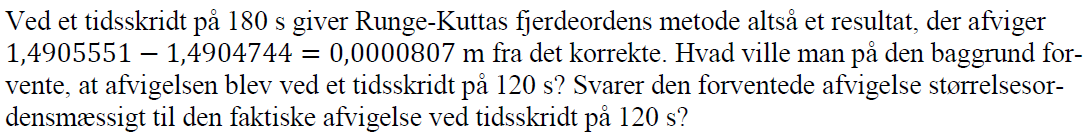

Man ville forvente at den ville være $\left( \frac{2}{3} \right)^4 \cdot 0,0000807$.

fejl_teori = (2/3)^4 * 0.0000807

fejl_teori = 1.5941e-05

fejl_faktisk = 1.4905551 - 1.4905421

fejl_faktisk = 1.3000e-05

Forskellen bliver således

delta_fejl = fejl_teori - fejl_faktisk

delta_fejl = 2.9407e-06

delta_fejl / fejl_teori * 100

ans = 18.4480

altså en forskel på $3 \cdot 10^{-6}$ eller en forskel på fejlen 18,45%.

## Opgave 3

clear
u = symunit;

### (3a)

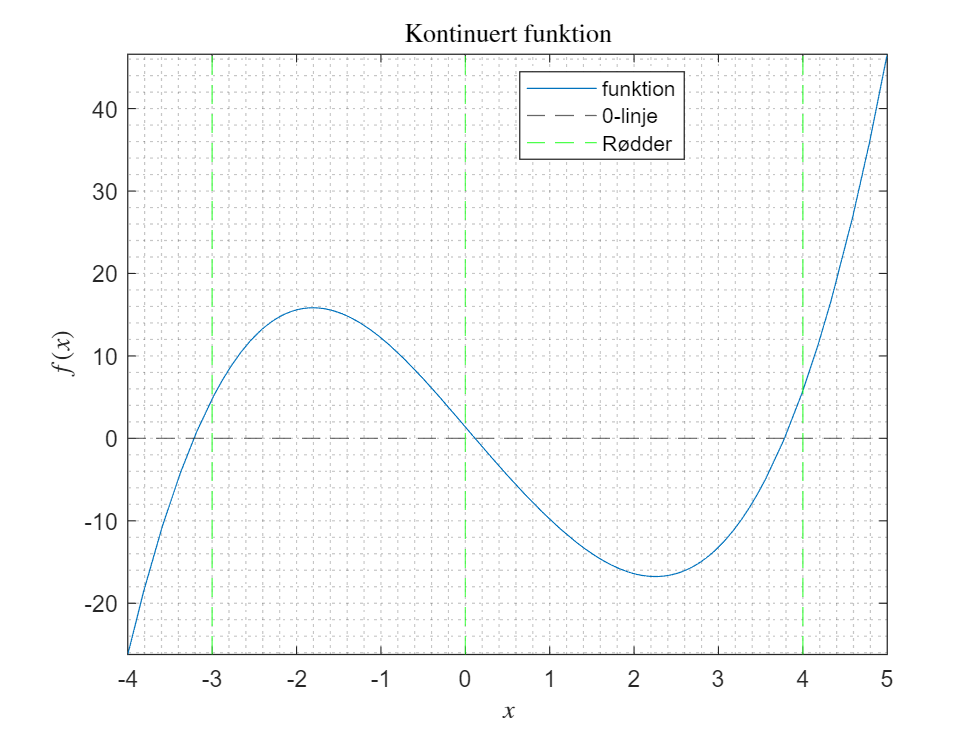

syms x

f(x) = x^3 - x^2 - 12*x + 2 * log(x^2 + 2);
%der plottes
fplot(f(x),[-4, 5], 'DisplayName', 'funktion') %data plottes
hold on
yline(0, '--', 'DisplayName', '0-linje')
xline([-3], 'g--', 'DisplayName', 'Rødder'); 
xline([0 4], 'g--','HandleVisibility','off');

% formalier
legend('location', 'best')
title('Kontinuert funktion', 'interpreter', 'latex')
xlabel('$x$', 'interpreter', 'latex')
ylabel('$f(x)$', 'interpreter', 'latex')
grid('minor')
hold off

**De aflæste rødder bliver således -3, 0 og 4**

### (3b)

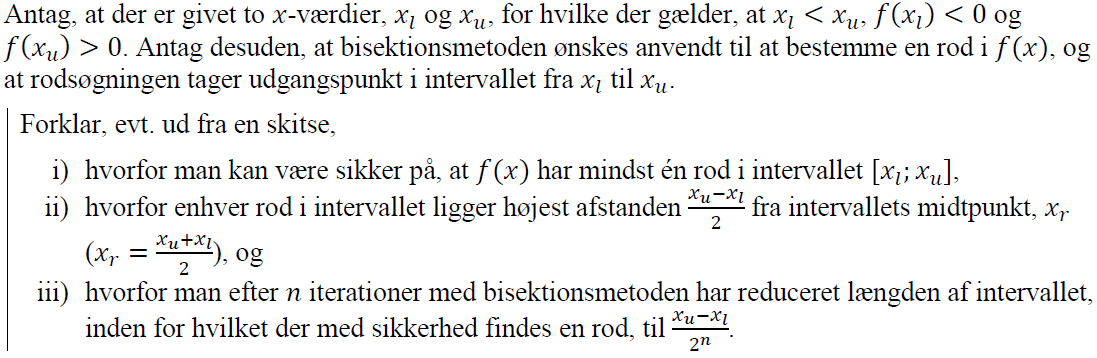

**i) **

Der kan være flere rødder hvis man som på grafen ovenfor vælger $x_l = -3,5$ og $x_u = 4$ så vil vi have overholdt kravende men have 3 rødder imellem de to punkter

Der vil dog altid være mindst en rod da funktionsværdierne går fra negativ til positiv og dermed krydser x-aksen f(x) = 0 som er en rod.

**ii)**

da $x_u - x_l$ definere afstanden imellem de to punkter og midtpunktet er  $\frac{x_u - x_l}{2}$ så vil roden rodens maximale afstand være hvis den ligger i $x_l$ eller $x_u$ og altså dermed halvejs til midtpuntket $\frac{x_u - x_l}{2}$.

**iii)**

Det sker fordi man bliver ved med at reducere med en halv $\frac{x_u - x_l}{2} \cdot \frac{1}{2}  \cdot \frac{1}{2}  \cdot \frac{1}{2}... = \frac{x_u - x_l}{2^n}$ at gange tal sammen i serie svare til at opløfte i antallet af gange der ganges på.

### (3c)

eval(f(-2))

ans = 15.5835

eval(f(5))

ans = 46.5917

Nej da begge værdier giver en positiv funktionsværdi. der kan således ikke kan vides om der findes en rod imellem punkterne da der ikke nødvendigvis krydser y = 0

### (3d)

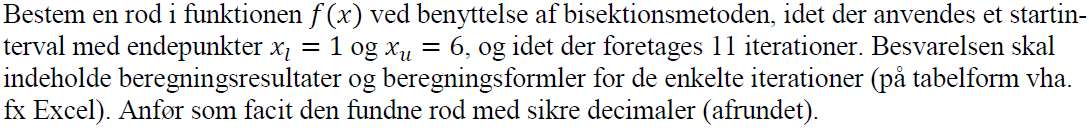

Vi benytter bisect funktionen ovenfor og ser samtidg på grafen at der kun er en rod i intervallet 1 til 6

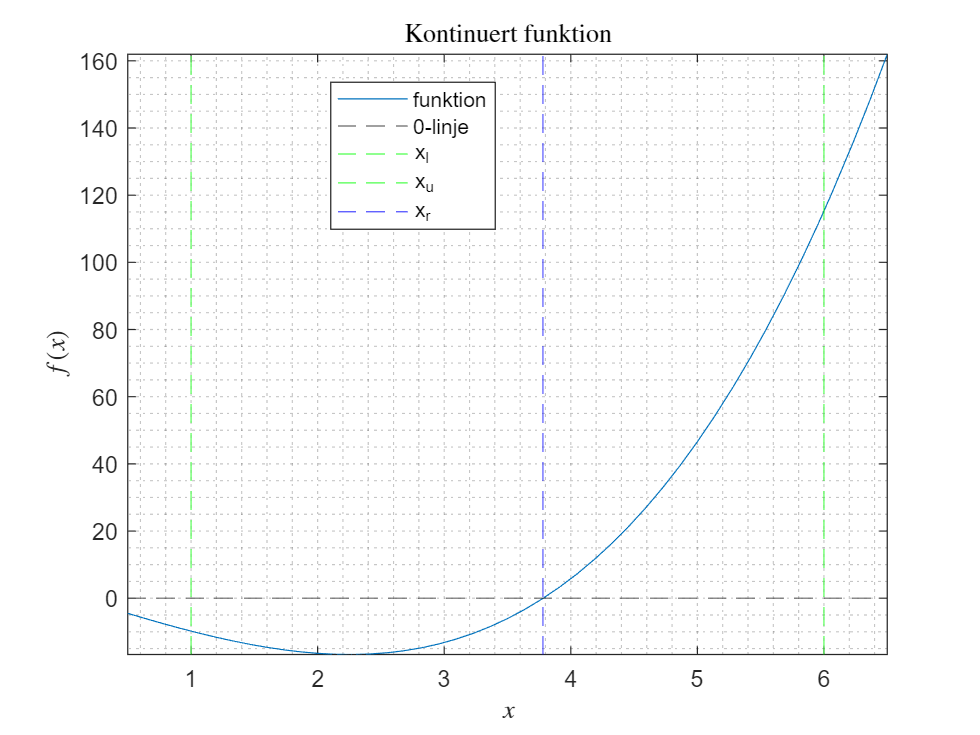

fplot(f(x),[0.5, 6.5], 'DisplayName', 'funktion') %data plottes
hold on
yline(0, '--', 'DisplayName', '0-linje')
xline([1], 'g--', 'DisplayName', 'x_l'); 
xline([6], 'g--', 'DisplayName', 'x_u');
xline([3.78], 'b--', 'DisplayName', 'x_r');
% formalier
legend('location', 'best')
title('Kontinuert funktion', 'interpreter', 'latex')
xlabel('$x$', 'interpreter', 'latex')
ylabel('$f(x)$', 'interpreter', 'latex')
grid('minor')
hold off

func = matlabFunction(f(x));
xl = 1;
xu = 6;
ea = 0.0001;
maxit = 11;
[root,fx,ea,iter]=bisect1(func,xl,xu,ea,maxit) 

root = 3.7808

fx = -0.0389

ea = 0.0646

iter = 11

med excel får vi

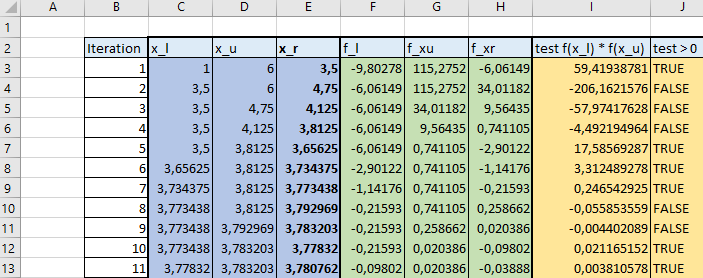

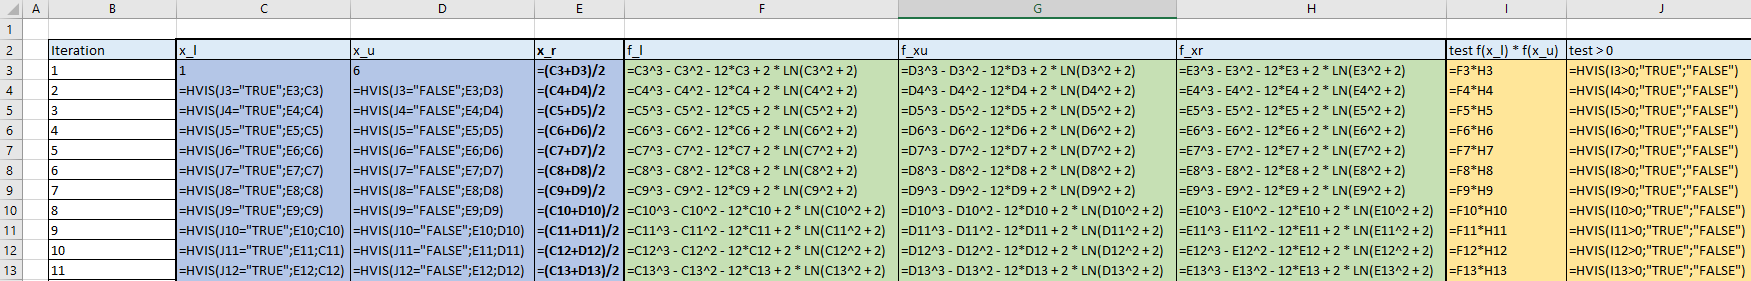

Ved iteration 11 for vi således roden 3,78 hvilket stemmer overens med 

### (3e)

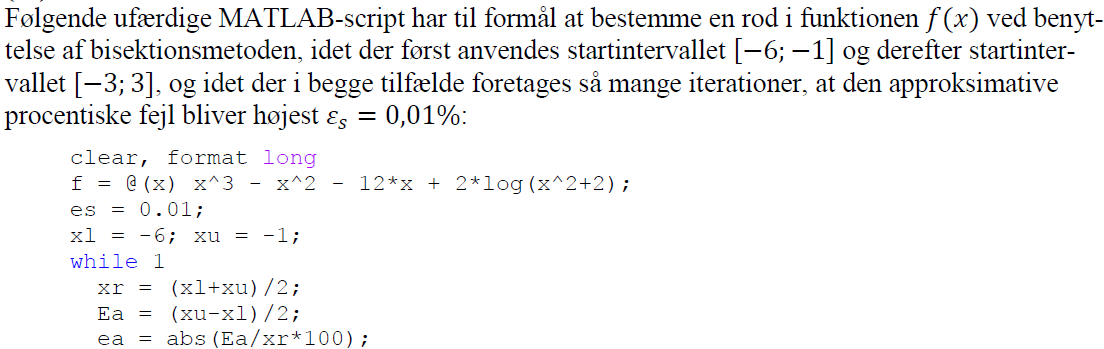

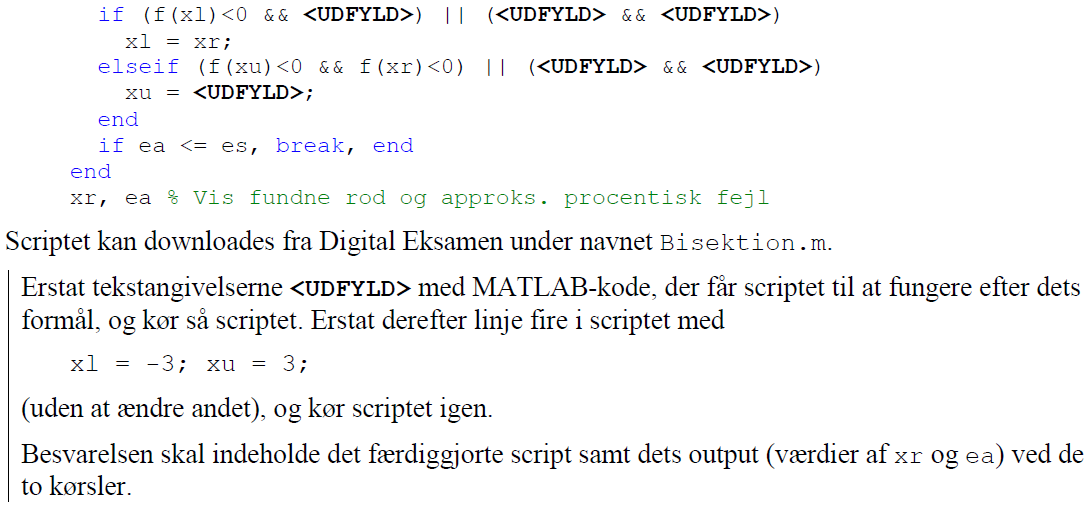

clear, format long
f = @(x) x^3 - x^2 - 12*x + 2*log(x^2+2);
es = 0.01;
xl = -6; xu = -1;
while 1
  xr = (xl+xu)/2;
  Ea = (xu-xl)/2;
  ea = abs(Ea/xr*100);
  if (f(xl) < 0 && f(xr) < 0) || (f(xl) > 0 && f(xr) > 0)
    xl = xr;
  elseif (f(xu) < 0 && f(xr) < 0) || (f(xu) > 0 && f(xr) > 0)
    xu = xr;
  end
  if ea <= es, break, end
end
xr, ea % Vis fundne rod og approks. procentisk fejl

xr =   -3.216491699218750


ea =    0.009487846069185


clear, format long
f = @(x) x^3 - x^2 - 12*x + 2*log(x^2+2);
es = 0.01;
xl = -3; xu = 3;
while 1
  xr = (xl+xu)/2;
  Ea = (xu-xl)/2;
  ea = abs(Ea/xr*100);
  if (f(xl) < 0 && f(xr) < 0) || (f(xl) > 0 && f(xr) > 0)
    xl = xr;
  elseif (f(xu) < 0 && f(xr) < 0) || (f(xu) > 0 && f(xr) > 0)
    xu = xr;
  end
  if ea <= es, break, end
end
xr, ea % Vis fundne rod og approks. procentisk fejl

xr =    0.115642547607422


ea =    0.009896091044038



xl = -6;
xu = -1;
ea = 0.01;
maxit = 11;
[root,fx,ea,iter]=bisect1(f,xl,xu,ea,maxit) 

root =   -3.214355468750000


fx =    0.053611393562698


ea =    0.075953212820902


iter =     11


## Opgave 4

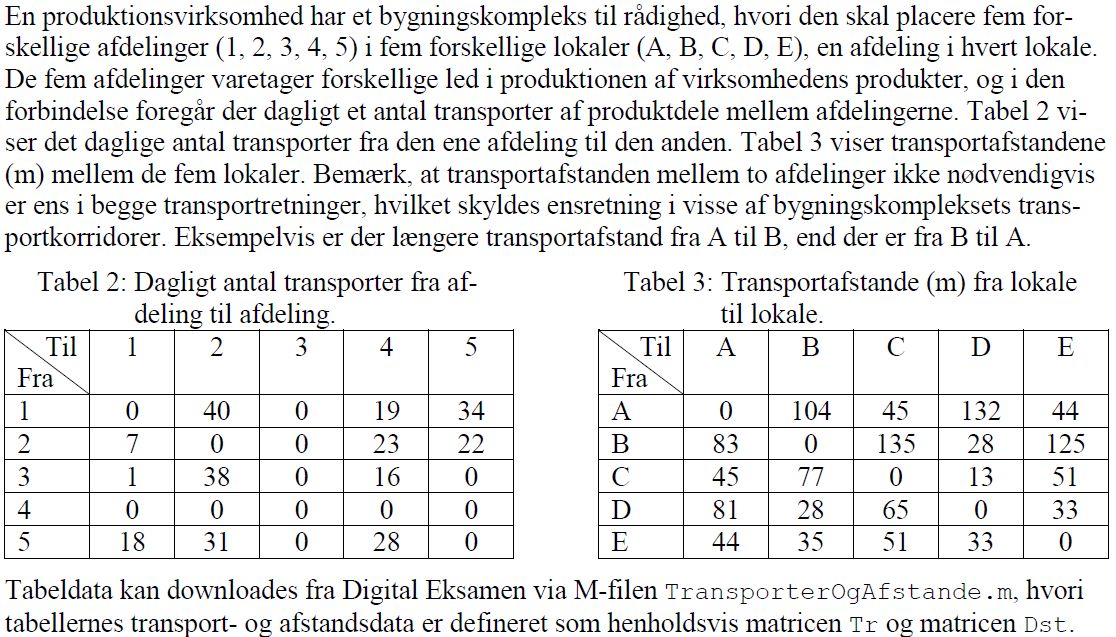

clear
TransporterOgAfstande;
Tr;% Dagligt antal transporter fra afdeling til afdeling
Dst;% Transportafstande (m) fra lokale til lokale

### (4a)

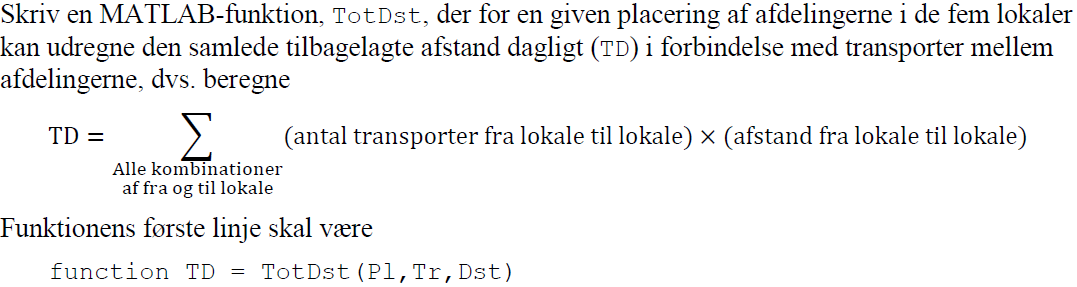

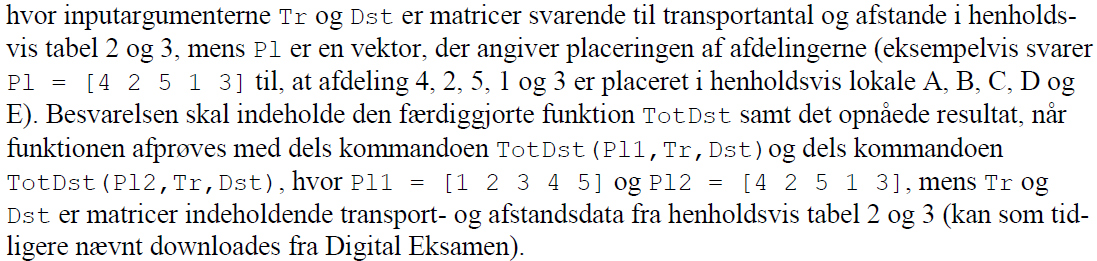

Pl1 = [1 2 3 4 5];
TD1 = TotDst(Pl1,Tr,Dst)

TD1 =        18119


Pl2 = [4 2 5 1 3];
TD2 = TotDst(Pl2,Tr,Dst)

TD2 =        15892


### (4b)

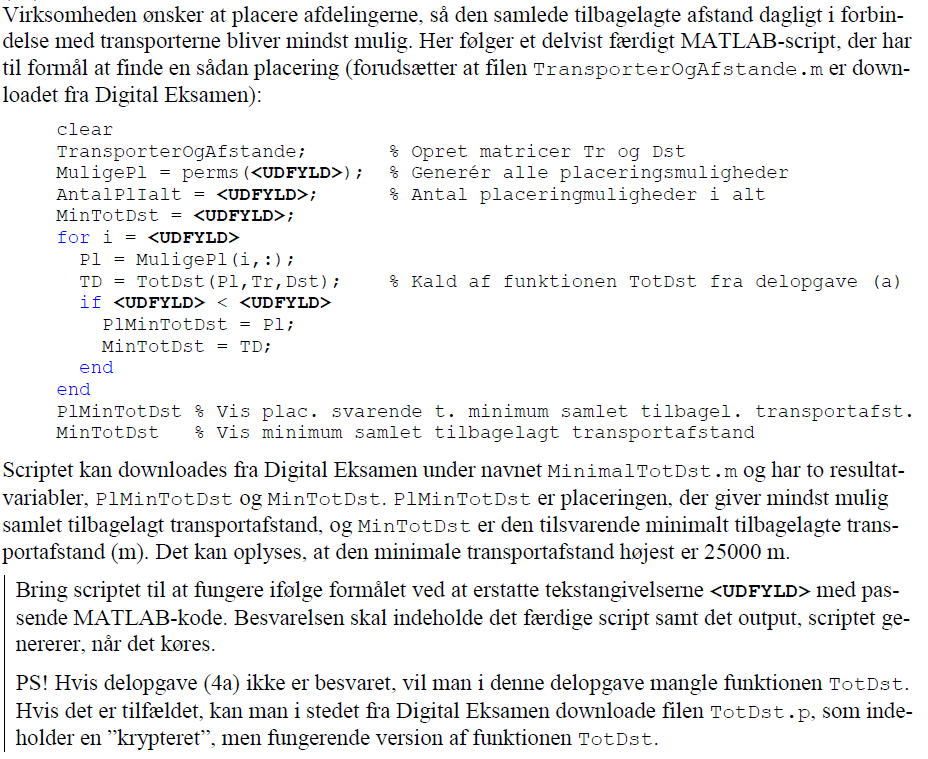

clear
TransporterOgAfstande; % Opret matricer Tr og Dst
MuligePl = perms(1:length(Tr)); % Generér alle placeringsmuligheder
AntalPlIalt = length(Tr); % Antal placeringmuligheder i alt
MinTotDst = 25000;
for i = 1:size(MuligePl, 1)
    Pl = MuligePl(i,:);
    TD = TotDst(Pl,Tr,Dst); % Kald af funktionen TotDst fra delopgave (a)
    if TD < MinTotDst
        PlMinTotDst = Pl;
        MinTotDst = TD;
    end
end

PlMinTotDst =      5     4     3     2     1


MinTotDst =        15711


PlMinTotDst =      5     4     2     3     1


MinTotDst =        15369


PlMinTotDst =      5     4     1     3     2


MinTotDst =        14016


PlMinTotDst =      4     5     3     2     1


MinTotDst =        12763


PlMinTotDst =      4     3     5     2     1


MinTotDst =        12512


PlMinTotDst =      4     3     1     2     5


MinTotDst =        11853


PlMinTotDst % Vis plac. svarende t. minimum samlet tilbagel. transportafst.

PlMinTotDst =      4     3     1     2     5


MinTotDst % Vis minimum samlet tilbagelagt transportafstand

MinTotDst =        11853


TD1 =        18119


TD2 =        15892
